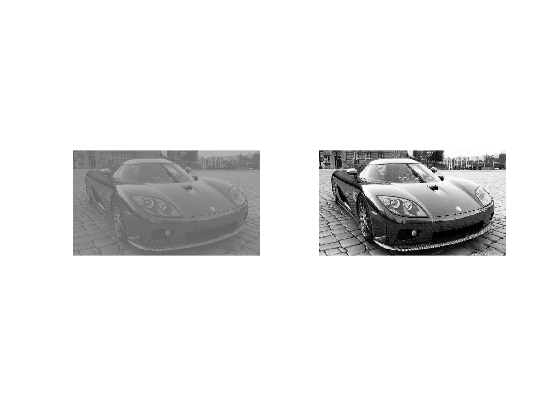

clc;clear all;close all;
im=double(imread('Image2.jpg'));
hist=figure;
[m,n,trash]=size(im);
R=im(:,:,1);
G=im(:,:,2);
B=im(:,:,3);
%%% RGB to YUV!
Y=0.299.*R+0.587.*G+0.114.*B;
U=-0.147.*R-0.289.*G+0.436.*B;
V=0.615.*R-0.515.*G-0.100.*B;
subplot(1,2,1);
histogram(uint8(Y));
%%% count!
count=zeros(1,256);
for i=1:m
    for j=1:n
        count(1,uint8(Y(i,j))+1)=count(1,uint8(Y(i,j))+1)+1;
    end
end
for i=1:256
    counter(1,i)=count(1,i)/(m*n);
end
%%% Equalize!
now=0;
map=zeros(1,256);
for i=1:256
    now=now+counter(1,i);
    map(1,i)=round(255*now);
end
%%% generate!
for i=1:m
    for j=1:n
        Y(i,j)=map(uint8(Y(i,j)));
    end
end
%%% YUV to RGB!
r=Y+1.14.*V;
g=Y-0.39.*U-0.58.*V;
b=Y+2.03.*U;
new(:,:,1)=r;
new(:,:,2)=g;
new(:,:,3)=b;
%%% output!
img=figure;
figure(img);
subplot(1,2,1);
imshow(uint8(im));
subplot(1,2,2);
imshow(uint8(new));

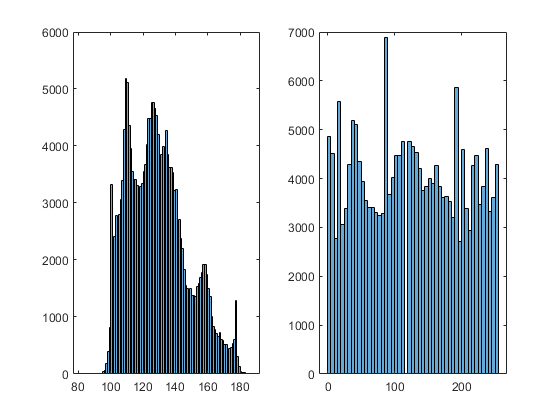

figure(hist);
subplot(1,2,2);
histogram(uint8(Y));